# Data analysis on COVID-19 in Italians regions (06-04-2020)

Data from : [https://github.com/pcm-dpc/COVID-19](https://github.com/pcm-dpc/COVID-19)

Created by Carlo Cenedese (c.cenedese@rug.nl)

clear all
close all
warning off;

% Add the function folder
path1 = '\COVID-19-master\dati-province';
addpath(genpath([pwd,path1]))
path2 = '\COVID-19-master\dati-regioni';
addpath(genpath([pwd,path2]))
path3 = '\COVID-19-master\dati-aree';
addpath(genpath([pwd,path3]))
path4 = '\fnc';
addpath(genpath([pwd,path4]))


## Upload the data

% Upload all the filename in a variable 'date'
files_names
for j = 1:length(date)
    name_file = [prefix,date(j,:),'.csv']; 
    TT(j).T = readtable(name_file); 
end

## Select the regions to compare

% Region code:
% 1  : Piemonte                     | 11 : Marche   
% 2  : Valle d'Aosta                | 12 : Lazio
% 3  : Lombardia                    | 13 : Abruzzo
% 4  : P.A. Trento                  | 14 : Molise
% 5  : Veneto                       | 15 : Campania
% 6  : Friuli Venezia Giulia        | 16 : Puglia
% 7  : Liguria                      | 17 : Basilicata
% 8  : Emilia-Romagna               | 18 : Calabria
% 9  : Toscana                      | 19 : Sicilia
% 10 : Umbria                       | 20 : Sardegna
Region_ID = [3, 5, 8];
% Regions population
Region_pop = [4392526, 126883, 10018806, 1062860, 4907529, 1217872,...
    1565307, 4448841, 3742437, 888908, 1538055, 5898124, 1322247,...
    310449, 5839084, 4063888, 570365, 1965128, 5056.641, 1653135];

## Extract all the data for the reagion

Date = [];
for j = 1:length(Region_ID)
    Region_Data = []; Date = [];
    for i = 1:length(TT)
        % Select the table row associated to the reagion
        ind_Region = find(TT(i).T.codice_regione == Region_ID(j));
        % The days associated to the data
        Date = [Date; cell2mat(TT(i).T.data(ind_Region))];
        %  Data of the contagion
        Region_Data = [Region_Data;
                    TT(i).T.ricoverati_con_sintomi(ind_Region),...  % # hospitalized
                    TT(i).T.totale_positivi(ind_Region),...         % total positives
                    TT(i).T.nuovi_positivi(ind_Region),...          % new cases
                    TT(i).T.deceduti(ind_Region),...                % deaths
                    TT(i).T.totale_casi(ind_Region),...             % total cases
                    TT(i).T.tamponi(ind_Region),...                 % total tests
                    Region_pop(Region_ID(j))];                      % region population
    end
    % In some cases the data are wrong, i.e., tot number of tests is decreasing. 
    % Fixed by putting the the same number of test as the previous day
    tot_tst = Region_Data(:,6); tot_tst2 = [0;Region_Data(:,6)]; tot_tst2(end) = [];
    ind_bad_test = find(tot_tst-tot_tst2 < 0); ind_bad_test2 = ind_bad_test-1;
    tot_tst(ind_bad_test) = tot_tst(ind_bad_test2);
    % number of daily test
    Region_Data(:,6) = tot_tst; tot_tst2 = [0;Region_Data(:,6)]; tot_tst2(end) = [];
    daily_tst = tot_tst-tot_tst2;
    Region_Data = [Region_Data, daily_tst]; 
    %%
    Region_cmp(j).name = TT(i).T.denominazione_regione(ind_Region);
    Region_cmp(j).data = Region_Data;
end
% Trim dates string 
Date = Date(:,6:10);


## 1) Total number of cases  and increment

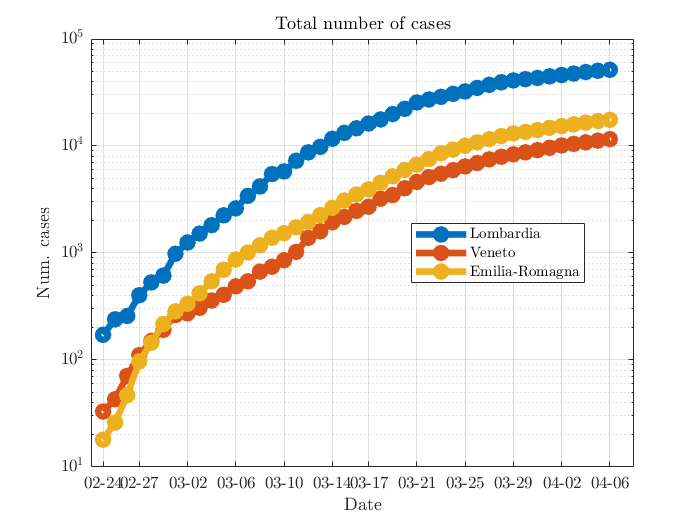

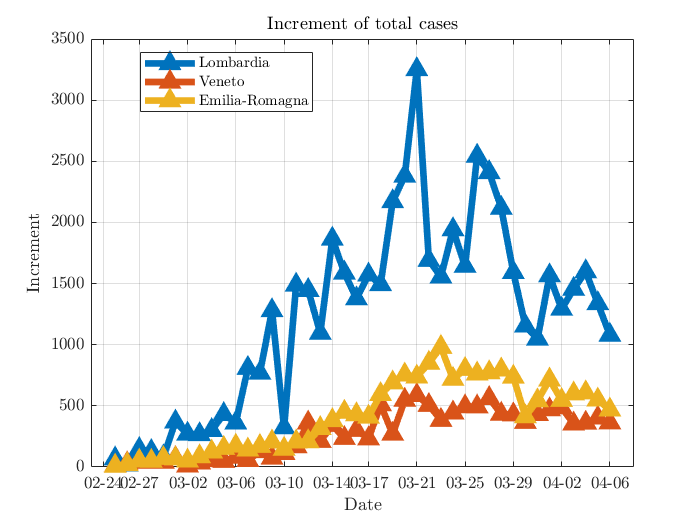

leg = strings(1,length(Region_cmp));leg2 = strings(1,length(Region_cmp));
for l = 1:length(Region_cmp)
    cases = Region_cmp(l).data(:,5);
    figure(1);
    semilogy(1:length(Date),cases,'o-','Linewidth',4)
    grid on; hold on
    title('Total number of cases');
    plot_style;
    ax.YAxis.Label.String = 'Num. cases';
    leg(l) = Region_cmp(l).name;
    [a,b] = legend(leg,'Location','best'); a.Interpreter = 'latex';
    
    figure(2)
    increment = cases- circshift(cases,1); increment(1) = NaN;
    plot(1:length(Date),increment,'^-','Linewidth',4)
    grid on; hold on
    title('Increment of total cases');
    plot_style;
    ax.YAxis.Label.String = 'Increment';
    leg2(l) = Region_cmp(l).name;
    [c,d] = legend(leg2,'Location','best'); c.Interpreter = 'latex'; 
    
end

## 2) Percentage of tests resulted positive

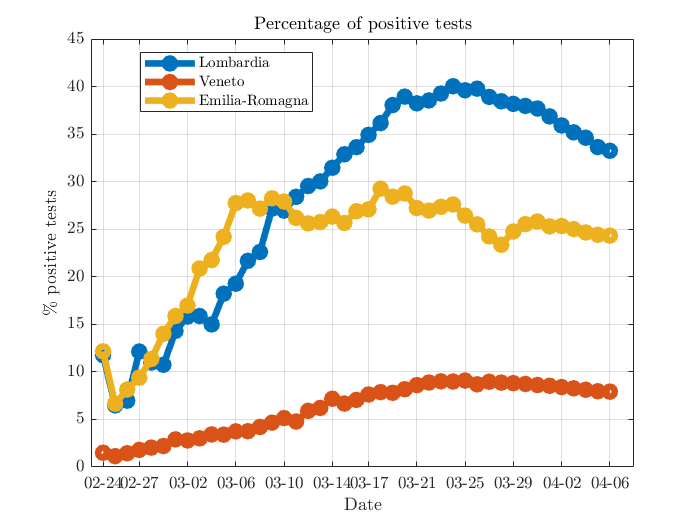

leg = strings(1,length(Region_cmp));
for l = 1:length(Region_cmp)
    cases = Region_cmp(l).data(:,5);
    total_cases = Region_cmp(l).data(:,5); d_tests = Region_cmp(l).data(:,6);
    % Percentage of positive tests
    perc_tst = total_cases./d_tests*100;
    
    figure(3)
    plot(1:length(Date),perc_tst,'o-','Linewidth',4)
    grid on; hold on
    title('Percentage of positive tests');
    plot_style;
    ax.YAxis.Label.String = '\% positive tests';
    leg(l) = Region_cmp(l).name;
    [a,b] = legend(leg,'Location','best'); a.Interpreter = 'latex';
    
end

## 3) Number of death per 100k 

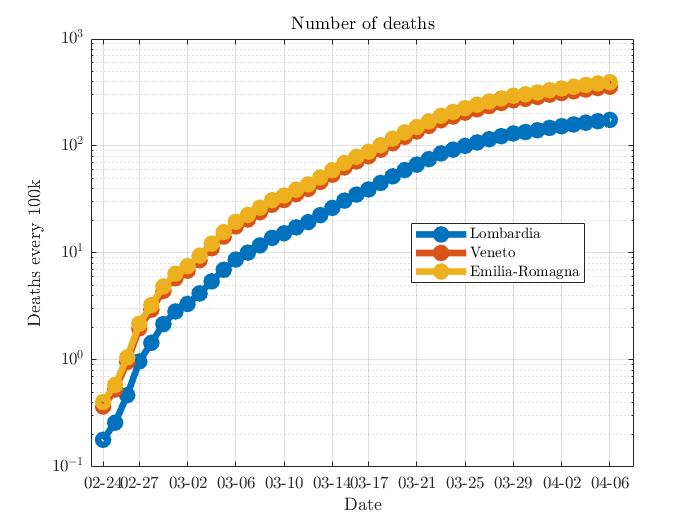

leg = strings(1,length(Region_cmp));
for l = 1:length(Region_cmp)
    deaths = Region_cmp(l).data(:,4);
    pop = Region_cmp(l).data(:,7);
    figure(4)
    semilogy(1:length(Date),cases./pop*10^5,'o-','Linewidth',4)
    grid on; hold on;
    title('Number of deaths');
    plot_style;
    ax.YAxis.Label.String = 'Deaths every 100k';
    leg(l) = Region_cmp(l).name;
    [a,b] = legend(leg,'Location','best'); a.Interpreter = 'latex';
end

## 4) Number of cases normalized for tests (last 20 days)

Every vector is divided by its maximum value to facilitate the plot. The "number of cases/ daily tests" is interesting because it takes into account the variation w.r.t. the growing number of tests performed. Therefore, it shows how some fast increments in the number of daily infected may be due to the increment in tests and not to a faster spread of the dissease.

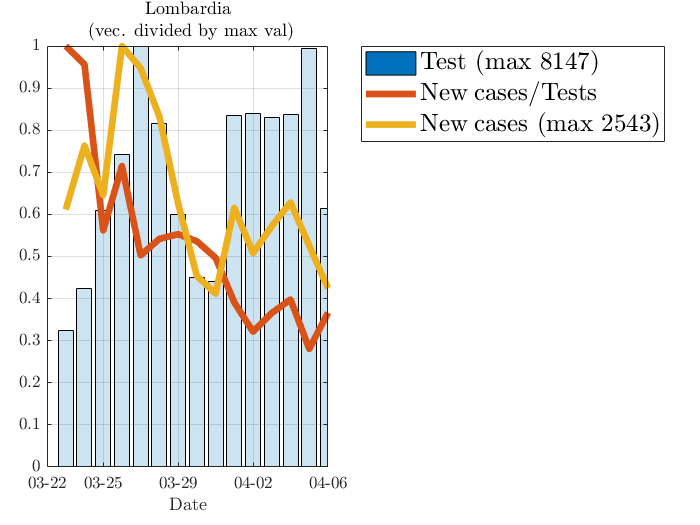

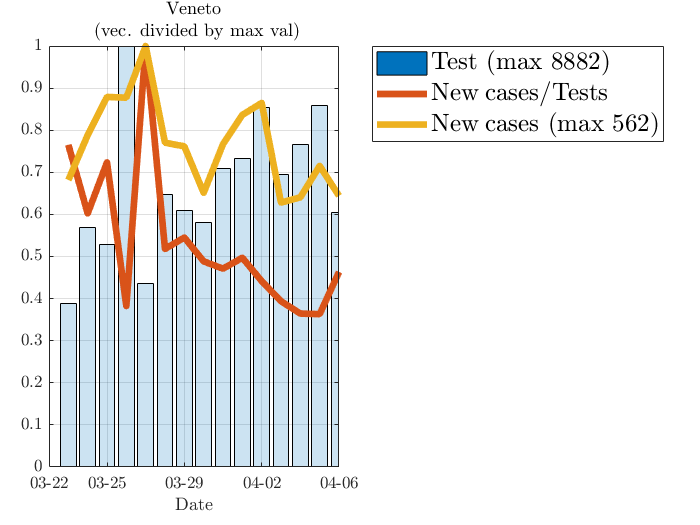

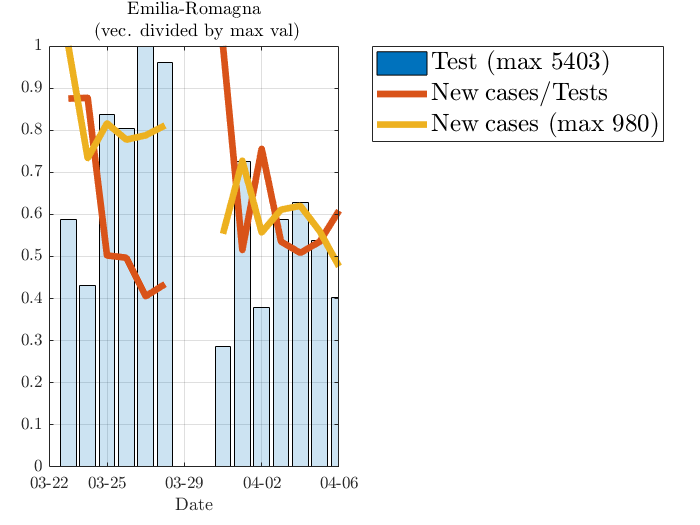

N = 15; % number of days to consider
for l = 1:length(Region_cmp)
    nuovi_pos = Region_cmp(l).data(:,3); nuovi_pos(1:end-N) = NaN;
    d_tests = Region_cmp(l).data(:,8);d_tests(1:end-N) = NaN;
    % find the days with no tests
    no_tst = find(d_tests == 0); nuovi_pos(no_tst) = NaN; d_tests(no_tst) = NaN;
    % if the # new cases > # tests => error
    ind_error = find(nuovi_pos > d_tests); nuovi_pos(ind_error) = NaN; d_tests(ind_error) = NaN;
    casi_normalizzati = nuovi_pos./d_tests.*(max(nuovi_pos./d_tests))^(-1);
    
    figure(4+l)
    bar(1:length(Date),d_tests./max(d_tests),'FaceAlpha',0.2)
    grid on
    hold on
    semilogy(1:length(Date),casi_normalizzati,'-','Linewidth',4)
    semilogy(1:length(Date),nuovi_pos/max(nuovi_pos),'-','Linewidth',4)
    title('New cases normalized');
    grid on; hold on;
    title([ Region_cmp(l).name,' (vec. divided by max val)' ]);
    tick_start = length(Date)-N; % plot only the last 20 days
    ax = gca; ax.XTick = 1:length(Date) ; ax.XTick = floor(linspace(tick_start,length(Date),5)); 
    ax.XTickLabel = Date(floor(linspace(tick_start,length(Date),5)),:);   ax.TickLabelInterpreter = 'Latex';
    ax.XAxis.Label.String = 'Date';  ax.XLabel.Interpreter = 'Latex'; 
    ax.YLabel.Interpreter = 'Latex'; ax.Title.Interpreter = 'Latex';
    ax.XLim = [length(Date)-N length(Date)];
    %ax.YAxis.Label.String = 'Deaths every 100k';
    str_tst =['$\mathrm{Test}$ (max ', num2str(max(d_tests)),')']; %'$\mathrm{Test}$'
    str_cases = ['$\mathrm{New\: cases}$ (max ', num2str(max(nuovi_pos)),')'];%'$\mathrm{New\: cases}$'
    [ll,mm] = legend(str_tst,'$\mathrm{New\: cases}/\mathrm{Tests} $', str_cases, 'Location','northeastoutside'); 
    ll.Interpreter = 'latex';
    ll.FontSize = 15;
    ll.Title.String = 'vectors div. by their max val';
end